**Interpolación Polinomica con forma de serie de potencias**

**a. **Un conjunto de cuatro puntos de datos está dado porr 

x = [1.1, 2.3, 3.9, 5.1]

y = [3.887, 4.276, 4.651, 2.117]

Encuentre los  coeficientes del polinomio de interpolación al conjunto de datos resolviendo la ecuacion y luego determine el valor de y para x= 2.101 y 4.234 mediante la fórmula de la interpolación. Grafique el polinomo junto con los puntos de datos.

**Solución:**

clear, clf, hold off
x= [1.1, 2.3, 3.9, 5.1]';
y= [3.887, 4.276, 4.651, 2.117]';
n=length(x)-1;
a(:,n+1)= ones(size(x));
a(:,n)=x;
for j=n-1:-1:1
    a(:,j)=a(:,j+1).*x;
end
coef=a\y 

coef =    -0.2015
    1.4385
   -2.7477
    5.4370


xi= [2.11, 4.234];
yi= zeros(size(xi))

yi =      0     0


for k=1:n+1
    yi=yi +coef(k)*xi.^(n+1-k)

end

yi =    -1.8924  -15.2905


yi =     4.5120   10.4975


yi =    -1.2856   -1.1363


yi =     4.1514    4.3007


yi

yi =     4.1514    4.3007


xp=1.1:0.05:5.1;
yp=zeros(size(xp));
for k=1:n+1
    yp= yp +coef(k)*xp.^(n+1-k)

end

yp =    -0.2681   -0.3064   -0.3481   -0.3935   -0.4426   -0.4956   -0.5528   -0.6141   -0.6799   -0.7502   -0.8251   -0.9049   -0.9897   -1.0797   -1.1749   -1.2755   -1.3818   -1.4937   -1.6116   -1.7355   -1.8656   -2.0021   -2.1450   -2.2947   -2.4511   -2.6144   -2.7849   -2.9626   -3.1477   -3.3403   -3.5407   -3.7489   -3.9652   -4.1895   -4.4223   -4.6634   -4.9132   -5.1717   -5.4392   -5.7157   -6.0014   -6.2965   -6.6011   -6.9154   -7.2395   -7.5736   -7.9178   -8.2723   -8.6372   -9.0127


yp =     1.4725    1.5961    1.7234    1.8542    1.9885    2.1261    2.2667    2.4103    2.5568    2.7059    2.8575    3.0114    3.1676    3.3258    3.4860    3.6478    3.8113    3.9763    4.1425    4.3099    4.4783    4.6475    4.8174    4.9879    5.1587    5.3298    5.5010    5.6722    5.8431    6.0137    6.1837    6.3531    6.5217    6.6893    6.8558    7.0210    7.1848    7.3470    7.5075    7.6662    7.8228    7.9772    8.1293    8.2790    8.4260    8.5702    8.7115    8.8497    8.9847    9.1163


yp =    -1.5500   -1.5638   -1.5739   -1.5804   -1.5835   -1.5833   -1.5801   -1.5738   -1.5648   -1.5531   -1.5389   -1.5223   -1.5035   -1.4827   -1.4599   -1.4354   -1.4093   -1.3818   -1.3529   -1.3229   -1.2919   -1.2601   -1.2276   -1.1945   -1.1610   -1.1273   -1.0935   -1.0597   -1.0262   -0.9930   -0.9603   -0.9283   -0.8971   -0.8669   -0.8378   -0.8100   -0.7836   -0.7587   -0.7356   -0.7143   -0.6951   -0.6781   -0.6633   -0.6511   -0.6415   -0.6346   -0.6307   -0.6299   -0.6323   -0.6381


yp =     3.8870    3.8732    3.8631    3.8566    3.8535    3.8537    3.8569    3.8632    3.8722    3.8839    3.8981    3.9147    3.9335    3.9543    3.9771    4.0016    4.0277    4.0552    4.0841    4.1141    4.1451    4.1769    4.2094    4.2425    4.2760    4.3097    4.3435    4.3773    4.4108    4.4440    4.4767    4.5087    4.5399    4.5701    4.5992    4.6270    4.6534    4.6783    4.7014    4.7227    4.7419    4.7589    4.7737    4.7859    4.7955    4.8024    4.8063    4.8071    4.8047    4.7989


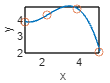

plot(xp,yp,x,y, 'o')
xlabel('x')
ylabel('y')